## Linear parametrization

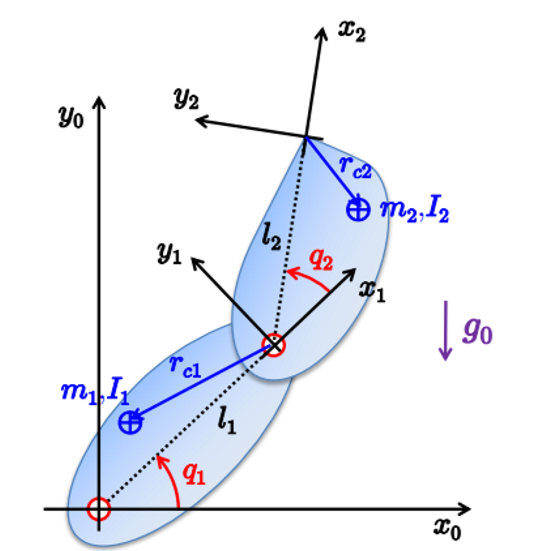

syms q1 q2 dq1 dq2 r_c1_x r_c1_y r_c2_x r_c2_y r_c1 r_c2 real
syms m1 m2 I1 I2 g0 l1 l2 real

% Joint 1
x1 = (l1-r_c1_x)*cos(q1);
y1 = r_c1_y*sin(q1);

vx1 = diff(x1,q1)*dq1 + diff(x1,q2)*dq2;
vy1 = diff(y1,q1)*dq1 + diff(y1,q2)*dq2;

T1_tr = 0.5*m1*[vx1 vy1]*[vx1; vy1;]

$$T1\_tr = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{r_{\mathrm{c1},y}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2}\,{\left(l_{1}-r_{\mathrm{c1},x}\right)}^{2}}{2}$$

T1_rot = 0.5*I1*dq1^2;

T1 = T1_tr+T1_rot;

% Joint 2 
R_02 = [cos(q1+q2) -sin(q1+q2);
        sin(q1+q2)  cos(q1+q2);];
p1 = [l1*cos(q1); l1*sin(q1);];
p2 = R_02*[(l2+r_c2_x);r_c2_y;];
p = p1+p2

$$p = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$


vx2 = diff(p(1),q1)*dq1 + diff(p(1), q2)*dq2

$$vx2 = -{\mathrm{dq}}_{1}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dq}}_{2}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)\right)$$

vy2 = diff(p(2), q1)*dq1 + diff(p(2), q2)*dq2

$$vy2 = {\mathrm{dq}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dq}}_{2}\,\left(\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)\right)$$


T2_tr = 0.5*m2*[vx2 vy2]*[vx2; vy2;]

$$T2\_tr = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{dq}}_{1}\,\left(\sigma_{2}-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dq}}_{2}\,\left(\sigma_{2}-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dq}}_{1}\,\left(\sigma_{1}+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+{\mathrm{dq}}_{2}\,\left(\sigma_{1}+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right) \end{array}$$

T2_rot = 0.5*I2*(dq1+dq2)^2;

T2 = T2_tr+T2_rot;

% Total Kinetic Energy
T=simplify(T1+T2, steps=10)

$$T = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{dq}}_{1}\,\left(\sigma_{2}-\sigma_{3}+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dq}}_{2}\,\left(\sigma_{2}-\sigma_{3}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dq}}_{1}\,\left(\sigma_{1}+\sigma_{4}+l_{1}\,\sin\left(q_{1}\right)\right)+{\mathrm{dq}}_{2}\,\left(\sigma_{1}+\sigma_{4}\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{r_{\mathrm{c1},y}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2}\,{\left(l_{1}-r_{\mathrm{c1},x}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)\\ \sigma_{3}=r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{4}=r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right) \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, steps=100);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\begin{array}{l} \left(\begin{array}{cc} I_{1}+I_{2}+m_{2}\,{\left(\sin\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)+r_{\mathrm{c2},y}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)}^{2}+m_{2}\,{\left(\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}+r_{\mathrm{c2},x}\right)-r_{\mathrm{c2},y}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)}^{2}+m_{1}\,{\sin\left(q_{1}\right)}^{2}\,{\left(l_{1}-r_{\mathrm{c1},x}\right)}^{2}+m_{1}\,{r_{\mathrm{c1},y}}^{2}\,{\cos\left(q_{1}\right)}^{2} & \sigma_{1}\\ \sigma_{1} & m_{2}\,{l_{2}}^{2}+2\,m_{2}\,l_{2}\,r_{\mathrm{c2},x}+m_{2}\,{r_{\mathrm{c2},x}}^{2}+m_{2}\,{r_{\mathrm{c2},y}}^{2}+I_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{l_{2}}^{2}+2\,m_{2}\,l_{2}\,r_{\mathrm{c2},x}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,l_{2}+m_{2}\,{r_{\mathrm{c2},x}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,r_{\mathrm{c2},x}+m_{2}\,{r_{\mathrm{c2},y}}^{2}-l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,r_{\mathrm{c2},y}+I_{2} \end{array}$$